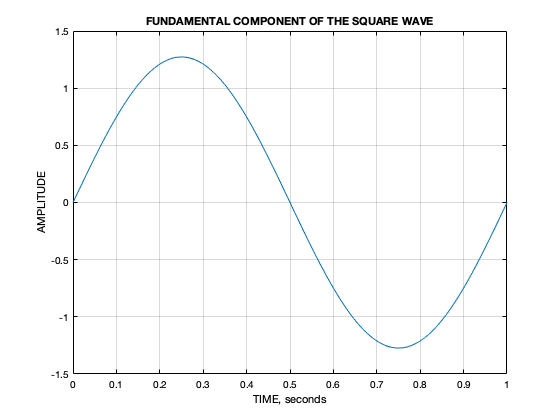

%fsCon.m
%Fourier Series Concept of Squarewave Signal %Modified on 01/28/22 by THA
close all; %delete all figures
clear all; %clear all parameters
format compact;  %Setting background of figures
whitebg('w');
f = 1; % Fundamental Frequency of sinusoid signal
T = 1/100; % Time spacing, 1/sampling freq. (fx)
t = 0:T:1; % time vector (1 sec with space 0.01)
y = 4/pi*sin(2*pi*f*t); % m=1 (order=1)
figure(1) % 1 -> figure 1 
plot(t,y), xlabel('TIME, seconds'); ylabel('AMPLITUDE');grid; title('FUNDAMENTAL COMPONENT OF THE SQUARE WAVE')

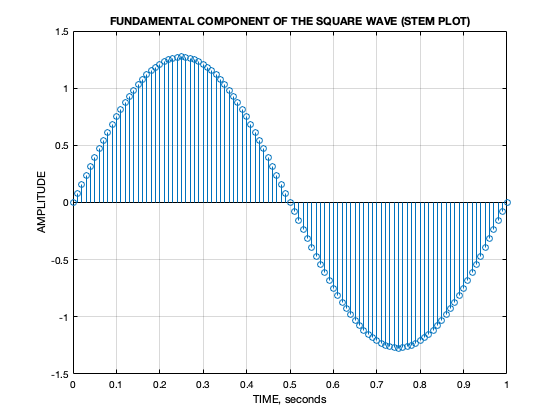

figure(2)
stem(t, y),  xlabel('TIME, seconds'); ylabel('AMPLITUDE');grid; title('FUNDAMENTAL COMPONENT OF THE SQUARE WAVE (STEM PLOT)')

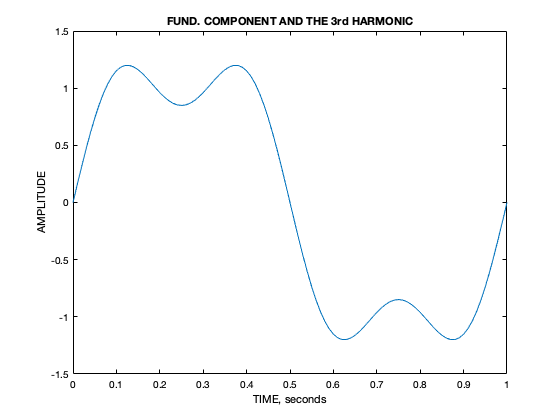

%Add in the 3rd-order harmonic
y = 4/pi*(sin(2*pi*f*t) + sin(2*pi*f*3*t)/3);
figure(3)
plot(t,y), xlabel('TIME, seconds'); ylabel('AMPLITUDE') 
title('FUND. COMPONENT AND THE 3rd HARMONIC')

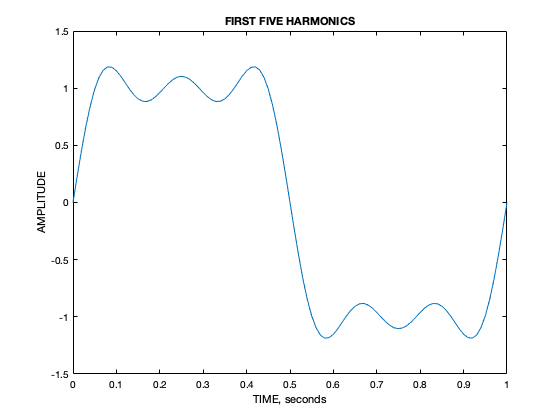

%The 5th-order harmonic
y = 4/pi*(sin(2*pi*f*t) + sin(2*pi*f*3*t)/3 + sin(2*pi*f*5*t)/5);
figure(4)
plot(t,y), xlabel('TIME, seconds'); 
ylabel('AMPLITUDE')
title('FIRST FIVE HARMONICS')

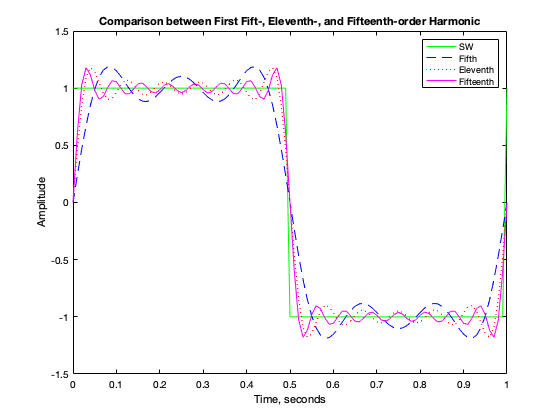

%Calculate MSE and compare between the first five and fifteen harmonics
x = zeros(size(t)); % Initial value of our FS param
sw = square(2*pi*f*t);
MeanSE= []; %MeanSE= zeros(8,1); 
harOrd= []; %harmonic Order
h= 1;
for k = 1:2:15 % harmonic Order (1,3,5,7,9,11,13,15)
    x = x+4*sin(2*pi*f*k*t)/(pi*k); %FS to be generated to match the original SW
    mseTmp= mse(sw-x); %Call MSE function 
    MeanSE= [MeanSE mseTmp];
    %MeanSE(h)= mseTmp;
    if k ==5
        y5 =x; % first five harmonics
    elseif k ==11
        y11 =x;  % first eleven harmonics
    elseif k ==15
        y15 =x;  % first fifteen harmonics
    end
    harOrd= [harOrd h];
    h= h+2; 
end;
%harOrd= [1:h-1];
figure(5); plot(t,sw,'g',t,y5,'b--',t,y11,'r:',t,y15,'m')
xlabel('Time, seconds'); ylabel('Amplitude')
title('Comparison between First Fift-, Eleventh-, and Fifteenth-order Harmonic')
legend('SW', 'Fifth', 'Eleventh', 'Fifteenth')

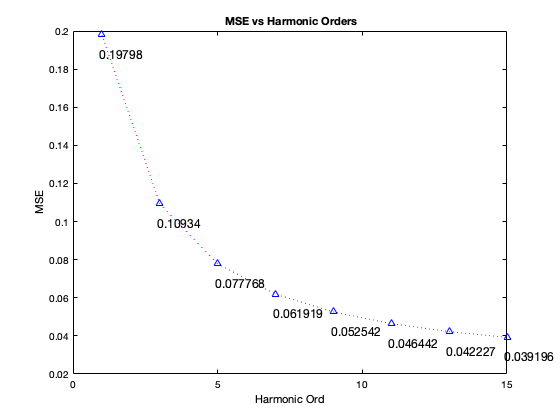


%Calculate MSE values of harmonic orders
figure(6),
for i=1:length(harOrd)
    plot(harOrd,MeanSE,':m', harOrd,MeanSE,'^b'),
    xlabel('Harmonic Ord'),ylabel('MSE'),
    title('\bf MSE vs Harmonic Orders'),
    mark= [num2str(MeanSE(i))];
    text(harOrd(i)-0.1,MeanSE(i)-0.01, mark,'FontSize',12) % display MSE value on the figure
    hold on;
end
hold off;

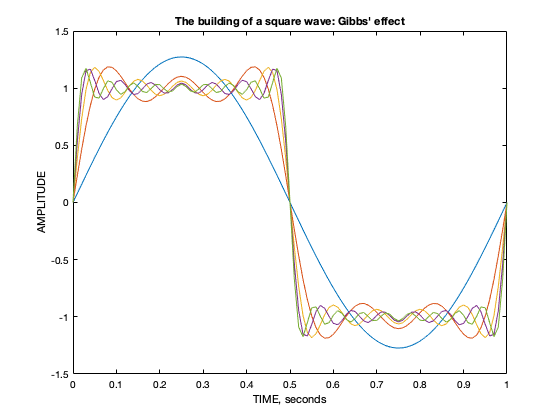

%
y = zeros(10,max(size(t)));
x = zeros(size(t));
for k=1:2:19
    x = x + 4*sin(2*pi*f*k*t)/(pi*k);
    y((k+1)/2,:) = x;
end
figure(7)
plot(t,y(1:2:9,:)'), xlabel('TIME, seconds');
ylabel('AMPLITUDE')
title('The building of a square wave: Gibbs'' effect');

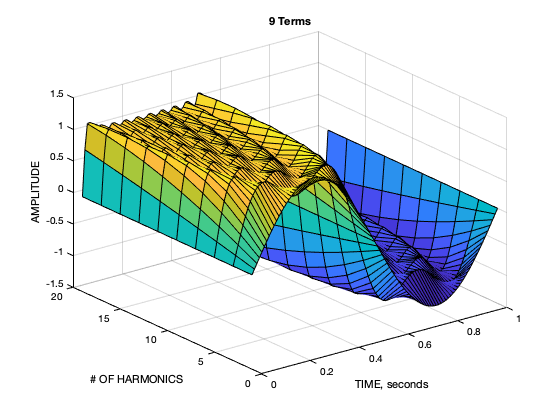

%
figure(8)
[har NY] = size(y); harv=[1:2:2*har];
surf(t,harv,y);
xlabel('TIME, seconds'); zlabel('AMPLITUDE'); 
ylabel('# OF HARMONICS')
title([int2str((k-1)/2) ' Terms'])